clc;
clear;
close all; 

% img = zeros(100,100);
% img(50,50)=255;
% %img = imread('im_cs.png');
% [x_dim_est, y_dim_est] = size(img);
% imshow(img,[],"InitialMagnification","fit");
% imwrite(uint8(img),'o.png');
% filename = 'random_dots.png';
filename = 'output_cs.png';
img = imread(filename);
[x_dim_est, y_dim_est] = size(img); % img 尺寸256 x 256

div = 1; %"zoom-factor"

x_dim = x_dim_est/div;
y_dim = y_dim_est/div;
z_dim = 1;

x_pos_est_full = linspace(-1,1,x_dim_est);
y_pos_est_full = linspace(-1,1,y_dim_est);
x_inx_full = linspace(-1,1,x_dim_est/div);
y_inx_full = linspace(-1,1,y_dim_est/div);
[x_inx_full, y_inx_full] = meshgrid(x_inx_full, y_inx_full);
[x_pos_est_full, y_pos_est_full] = meshgrid(x_pos_est_full, y_pos_est_full);

mag_full = 2 / x_dim ;
min_contrib = 1;

1 contribution points.


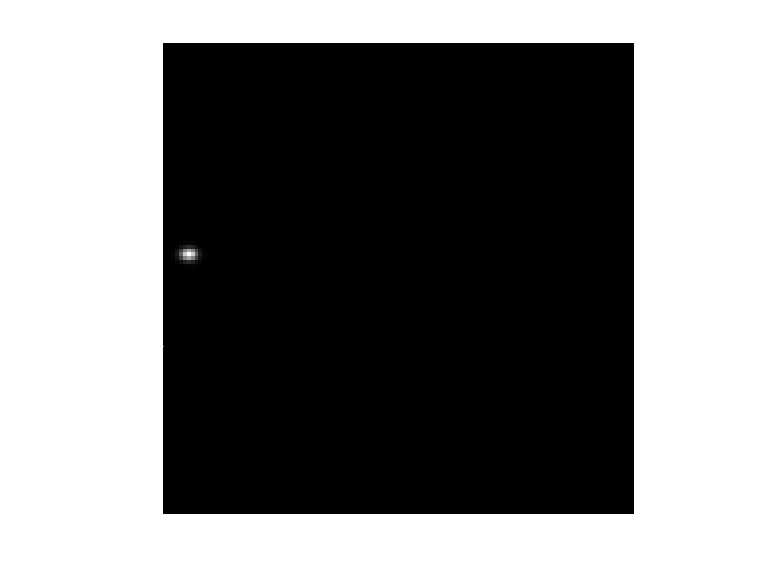

im_recover = zeros(x_dim, y_dim);
im = double(img);

for uu = 1:z_dim
    inx_contribute = find(im(:) >= min_contrib);
    if isempty(inx_contribute)
        fprintf('nothing found.\n');
        continue;
    else
        fprintf('%d contribution points.\n',length(inx_contribute(:)));
    end

    % calculate the recovered low resolution image based on the optimization results
    lowresimg_temp = zeros(x_dim,y_dim);
    for jj = 1:length(inx_contribute)
        h = MolKernel(x_inx_full, y_inx_full, ...
            x_pos_est_full(inx_contribute(jj)),...
            y_pos_est_full(inx_contribute(jj)), mag_full);
        A(:,jj) = h(:);
        lowresimg_temp = lowresimg_temp + im(inx_contribute(jj))*h;
    end

    c = sum(A);
    PSF_integ = max(c); % integration of the PSF over space, used for normalization

    im_recover = max(im_recover, lowresimg_temp / PSF_integ);
    imshow(im_recover,[],"InitialMagnification","fit");
    adjusted_image = imadjust(im_recover, stretchlim(im_recover), [0, 1]);
    imwrite(uint16(adjusted_image*255), [filename(1:end-4), '_r.png']);
    %imagesc((im_recover)), colormap(gray), hold on; drawnow;

end

%imwrite(uint8(im_recover),strcat(filename(1:end-4),'_r.png'));